# **Task_01b:**  Modal extraction (Sys ID) of an Impact test on a  3-floor-tower with **Stationary** Ground 

Recall the parametric equation of a Frequency Response Function (FRF) of a Mechanical structure:

- 
$$\mathrm{FRF}=\;\left(\sum_{k=1}^N \left.\frac{R_k }{s-\lambda_k }+\;\frac{\bar{R_k } }{s-\bar{\lambda_k } }\right)\;\;\;+\;\;e\;\;+\;\;\;\;\frac{f}{s^2 }\right.$$
          

where we have:

- **MODAL poles**:       $\lambda_k \;\;\;=\;-\zeta_k \ldotp \omega_{n_k } \;\;\;+\;\;\;j\ldotp \omega_{n_k } \ldotp \sqrt{\;1\;-{\zeta_k }^2 \;}$

- **RESIDUES**:            $R$

So ? - So in this script we'll analyze the Simulation data produced by [`TASK_01a_3floor_tower_STATIONARY_GROUND_impact_test.mlx`](matlab:  open TASK_01a_3floor_tower_STATIONARY_GROUND_impact_test.mlx) .  Specifically we'll:

- Convert the measured times series data into **Frequency Response Functions **(FRFs) using [`modalfrf()`](matlab:  doc modalfrf)

- **Extract the MODAL poles** from the FRFs using [`modalsd()`](matlab:  doc modalsd) and [`modalfit()`](matlab:  doc modalfit)

- Compute the **MODE shapes** of each identified mode

- Compare the Fitted FRFs against the measured FRFs

The **Extraction of the MODAL poles** is summarized by the workflow pipeline:

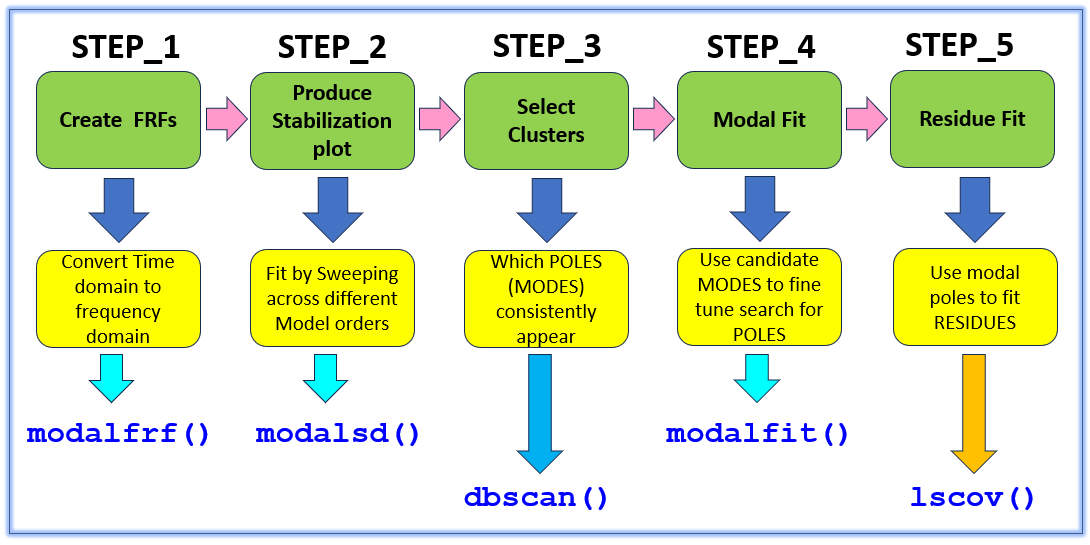

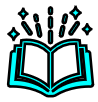 You can read-up on the DOC for the 5 main functions that we'll be utilizing here:

- **Signal Processing Toolbox**

- [`modalfrf()`](matlab:  doc modalfrf)` , `[`modalsd()`](matlab:  doc modalsd)` , `[`modalfit()`](matlab:  doc modalfit)

- **Statistics and Machine Learning Toolbox**

- [`dbscan()`](matlab: doc dbscan)

- **MATLAB**

- [`lscov()`](matlab: doc lscov) 

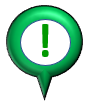**NOTE:**  

- For some background information on the MODAL model representation of a Mechanical system, see the following companion document  [`APPENDIX_01_Modal_Model_Representation.mlx`](matlab:  open  bh_Modal.APPENDIX_01_Modal_Model_Representation)

- In **Tutorial_03** we walk through a smaller case study on Experimental Modal Analysis(EMA) which also provides more insights into the "how and why" of extracting modal quantities from measured data

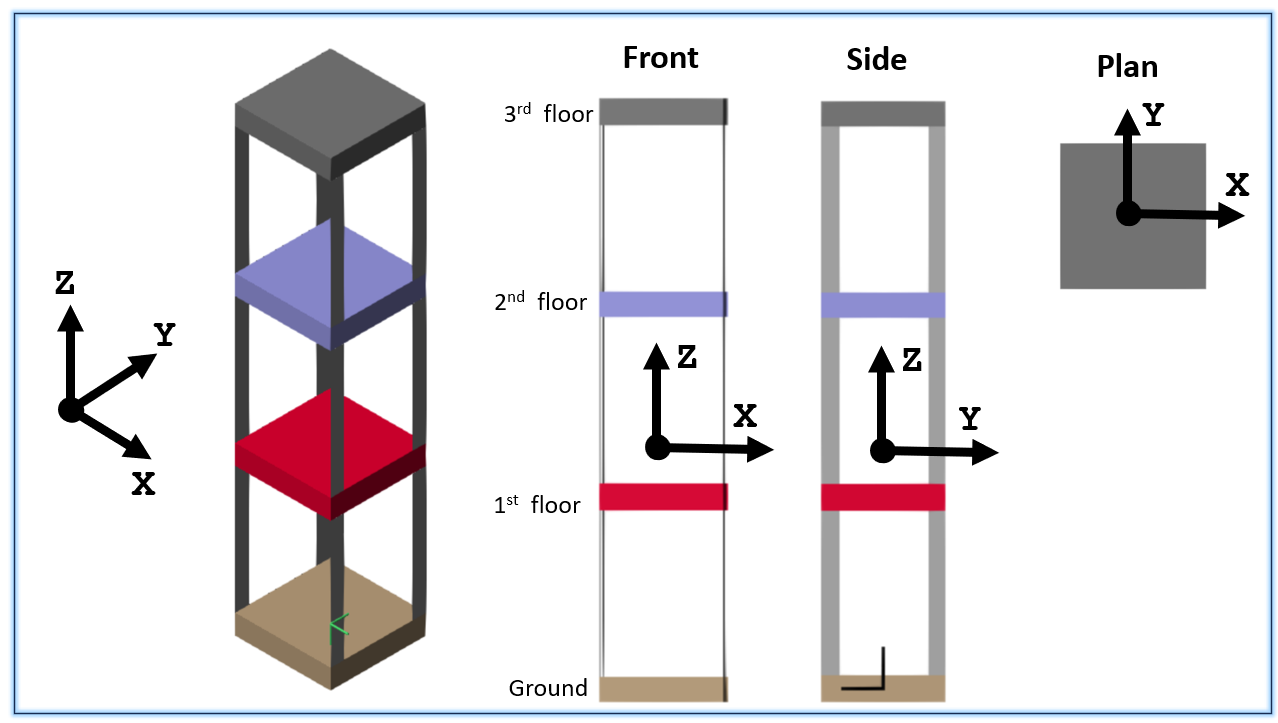

`Bradley Horton:  bhorton@mathworks.com`

# Load in the Time Series measurement data

Clear your Workspace

clear

Recall that our time series data was generated in the script 

- [`TASK_01a_3floor_tower_STATIONARY_GROUND_impact_test.mlx`](matlab:  open TASK_01a_3floor_tower_STATIONARY_GROUND_impact_test.mlx)

 **NOTE:**  the extracted resonant frequencies ***are almost identical***  (within 0.01 Hz for first 3 modes) regardless of whether 1,3 or 5 elements were used to parameterize each column

MEAS_tab   = readtable("bh_IMPACT_TEST.xlsx");

%MEAS_tab   = readtable("bh_IMPACT_TEST_25N.xlsx"); % 1 ele
%MEAS_tab   = readtable("bh_IMPACT_TEST_25N_3eles.xlsx");
%MEAS_tab   = readtable("bh_IMPACT_TEST_25N_5eles.xlsx");

whos MEAS_tab

  Name             Size             Bytes  Class    Attributes

  MEAS_tab      6001x7             339519  table              



So what are the raw column names

MEAS_tab.Properties.VariableNames'

ans = 7×1 cell array
    {'time'    }
    {'my_IO_F1'}
    {'my_IO_F2'}
    {'my_IO_F3'}
    {'my_IO_X1'}
    {'my_IO_X2'}
    {'my_IO_X3'}


Rename the COLUMNS

MEAS_tab.Properties.VariableNames = ["t","F1","F2", "F3", "X1","X2", "X3"]

MEAS_tab = 6001×7 table
     t      F1    F2    F3        X1             X2             X3     
    ____    __    __    __    ___________    ___________    ___________

       0    0     0     0               0              0              0
    0.01    0     0     0               0              0              0
    0.02    0     0     0               0              0              0
    0.03    0     0     0               0              0              0
    0.04    0     0     0               0              0              0
    0.05    0     0     0               0              0              0
    0.06    0     0     0               0              0              0
    0.07    0     0     0      1.1102e-16              0    -5.5511e-17
    0.08    0    

So how big is our MEASUREMENT data

whos MEAS_tab

  Name             Size             Bytes  Class    Attributes

  MEAS_tab      6001x7             339441  table              



Plot ***some*** of the measured **timeseries data**

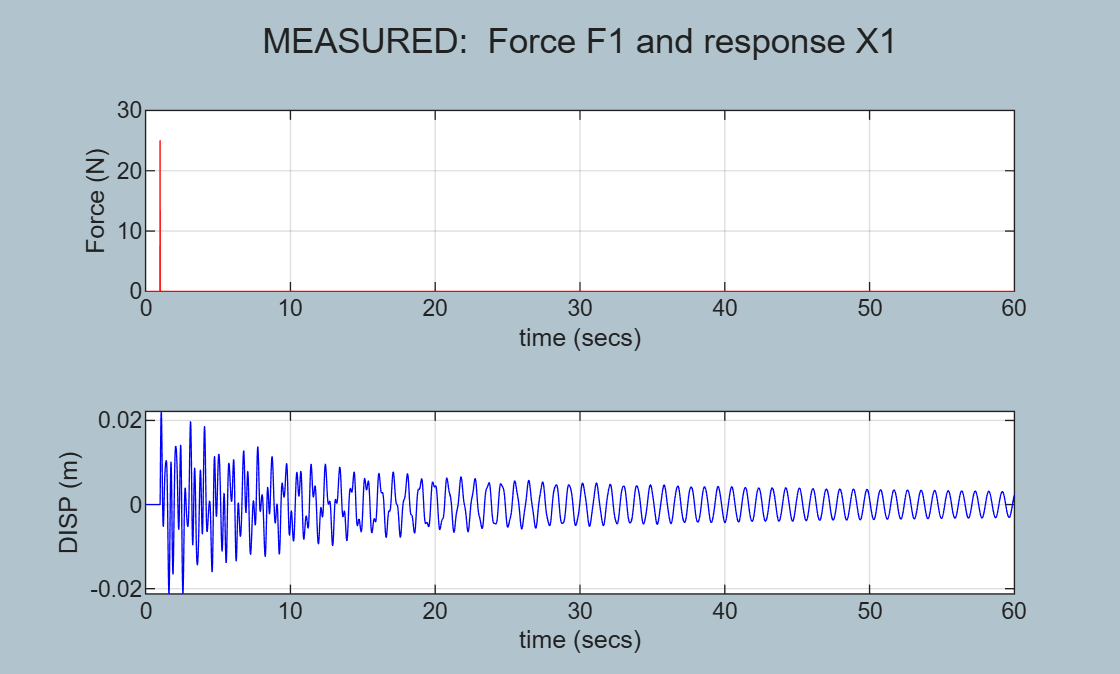

figure
tiledlayout(2,1)

nexttile
    plot(MEAS_tab.t, MEAS_tab.F1, "-r"); 
        xlabel("time (secs)"); ylabel("Force (N)"); grid on

nexttile
    plot(MEAS_tab.t, MEAS_tab.X1, "-b"); 
       xlabel("time (secs)"); ylabel("DISP (m)"); grid on

sgtitle("MEASURED:  Force F1 and response X1")

# Configure some signal processing parameters

### Define Fs

Define the sampling frequency 

Fs_hz     = 1/(MEAS_tab.t(2) - MEAS_tab.t(1))

Fs_hz = 100

### Define U and Y

Define the input(FORCE) and response(DISPLACEMENTS) data

in_col         = MEAS_tab.F1;
out_mat        = MEAS_tab{:, 5:end};

out_dof_labels = string(MEAS_tab.Properties.VariableNames(5:end));

### Define window attributes

-  **NOTE:**  the Exponential window has an OFFSET such that it does NOT effect the impact force signal.  

THE_WINDOW = bh_create_expon_window(MEAS_tab.t, F_col=in_col);
n_OVERLAP  = 0;

Sunlight test:  what will the windowed timeseries data look like?

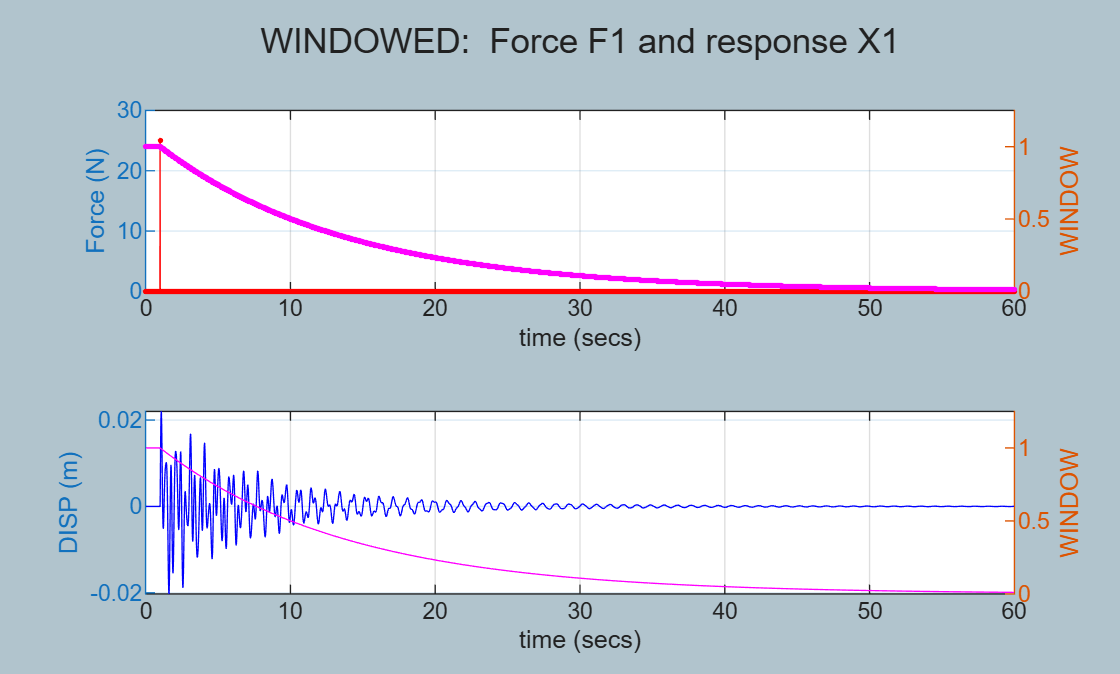

figure
tiledlayout(2,1)

nexttile
    yyaxis left
    plot(MEAS_tab.t, THE_WINDOW .* MEAS_tab.F1, "-r."); 
        xlabel("time (secs)"); ylabel("Force (N)"); grid on
    yyaxis right
        plot(MEAS_tab.t, THE_WINDOW, "-m."); ylabel("WINDOW"); ylim([0, 1.25])

nexttile
    yyaxis left
    plot(MEAS_tab.t, THE_WINDOW .* MEAS_tab.X1, "-b"); 
        xlabel("time (secs)"); ylabel("DISP (m)"); grid on
    yyaxis right
        plot(MEAS_tab.t, THE_WINDOW, "-m"); ylabel("WINDOW");  ylim([0, 1.25])

sgtitle("WINDOWED:  Force F1 and response X1")

# **STEP_1:**    Estimate the Systems FRF

 **DOC**:   see [`modalfrf()`](matlab:  doc modalfrf)  - NOTE we're stating that the RESPONSE sensor type is **DISPLACEMENT**

[all_frf, all_f] = modalfrf( in_col, out_mat, Fs_hz, ...
                             THE_WINDOW, n_OVERLAP, Sensor="dis");

whos  all_frf  all_f

  Name            Size             Bytes  Class     Attributes

  all_f        3001x1              24008  double              
  all_frf      3001x3             144048  double    complex   



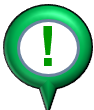 **NOTE:**  the frequency vector `all_f` (in Hz) that is returned only includes frequencies up to the NYQUIST frequency

all_f(end)

ans = 49.9917

## **Visualize the estimated FRFs**

meas.frf       = all_frf;
meas.f_hz      = all_f; 
meas.w         = 2*pi*meas.f_hz;
meas.frf_dB    = 20*log10(abs(meas.frf));
meas.phase_deg = rad2deg(  angle(meas.frf)   );

## Specify the Frequency range of interest and PLOT

roi.range_Hz = [0, 10];

tmp_ind      = find( (meas.f_hz > roi.range_Hz(1)) & (meas.f_hz < roi.range_Hz(2))  );

roi.f_Hz     = meas.f_hz(tmp_ind);
roi.frf      = meas.frf(tmp_ind, :);

And plot the ROI too

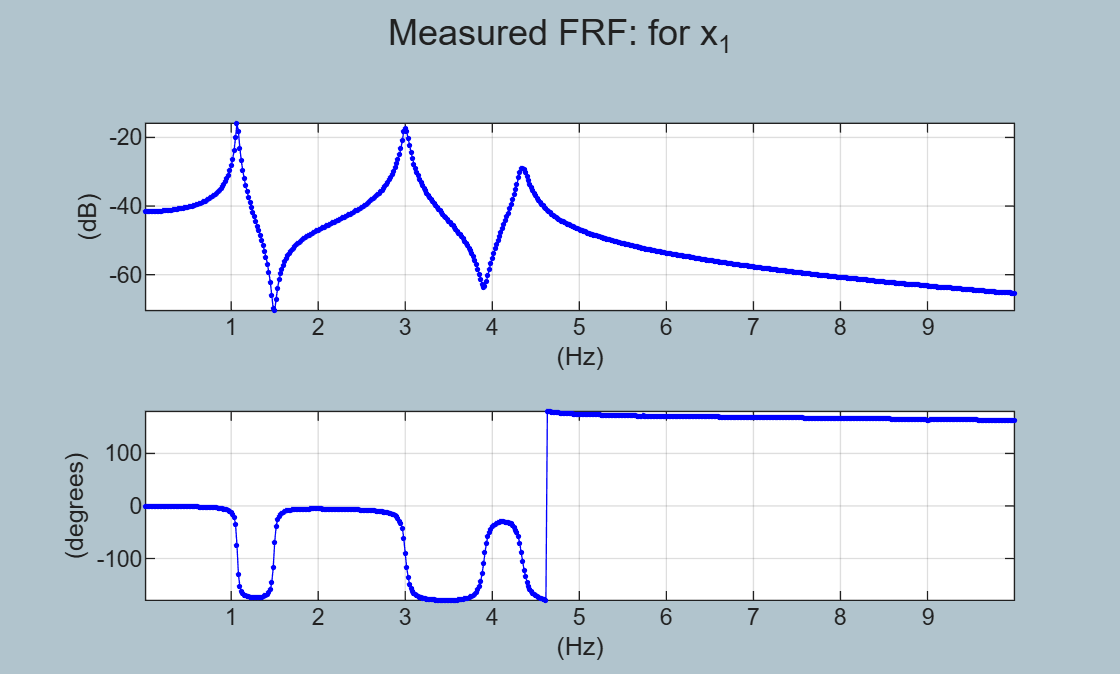

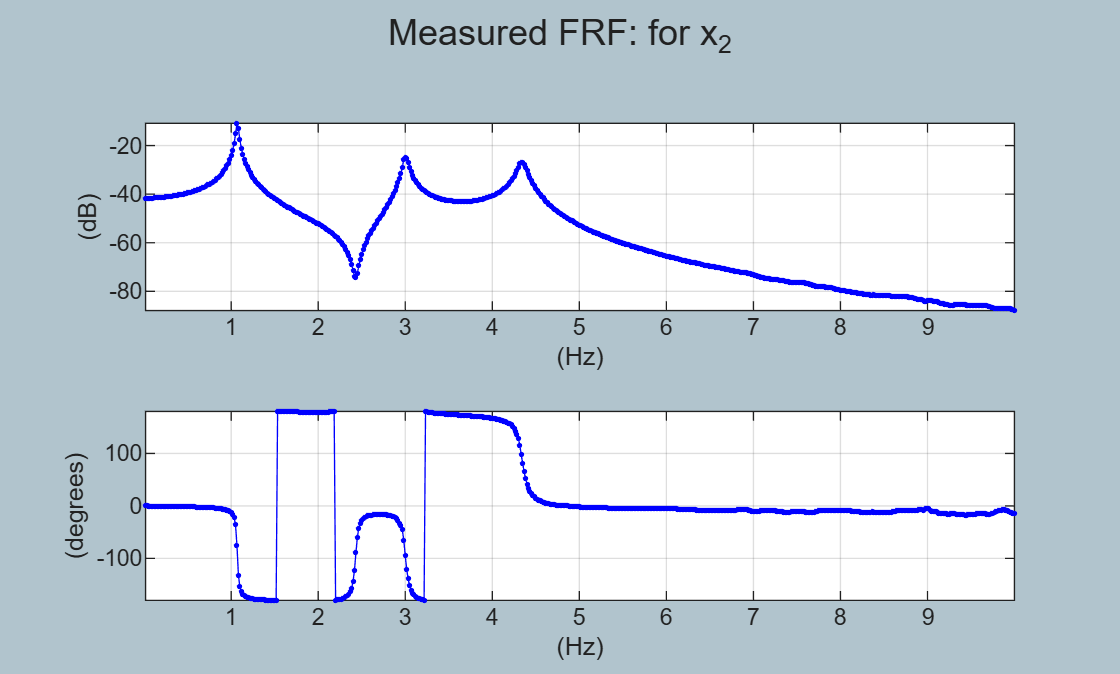

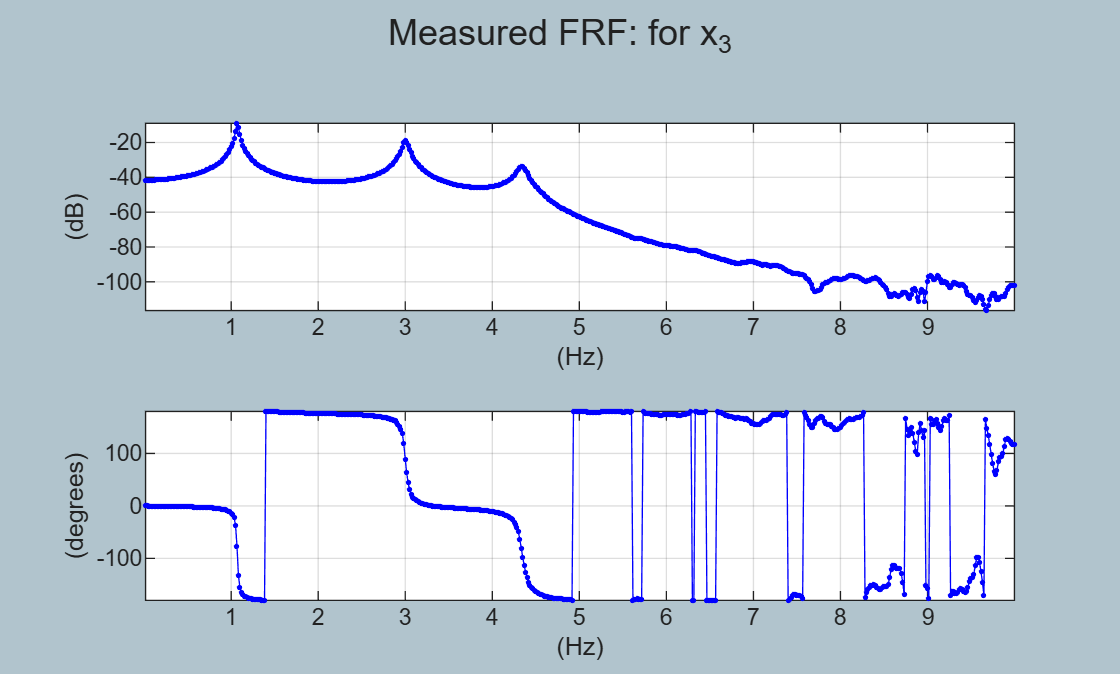

for kk=1:width(meas.frf)

    figure;
          hax(1) = subplot(2,1,1); 
               plot(roi.f_Hz, 20*log10( abs(roi.frf(:,kk))), "-b.", "DisplayName","MEAS")
                   grid on; axis tight
                   xlabel("(Hz)");   ylabel("(dB)");
    
          hax(2) = subplot(2,1,2); 
               plot(roi.f_Hz, rad2deg( angle(roi.frf(:,kk)) ), "-b.")
                   grid on; axis tight
                   xlabel("(Hz)");  ylabel("(degrees)")

          sgtitle("Measured FRF: for x_"+kk)         
end

# **STEP_2:**    Produce Stabilization plot

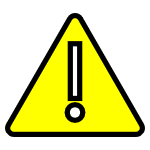 **NOTE:  **for this Cantilever data set (SIMO) .. the LSRF method is tooooo slow ...So I recommend you do NOT select that

try_it_FitMethod = "lsce";

### Consider the Stabilization diagram

 **DOC**:   see  [`modalsd()`](matlab:  doc modalsd)

We'll use ALL of our FRF channels

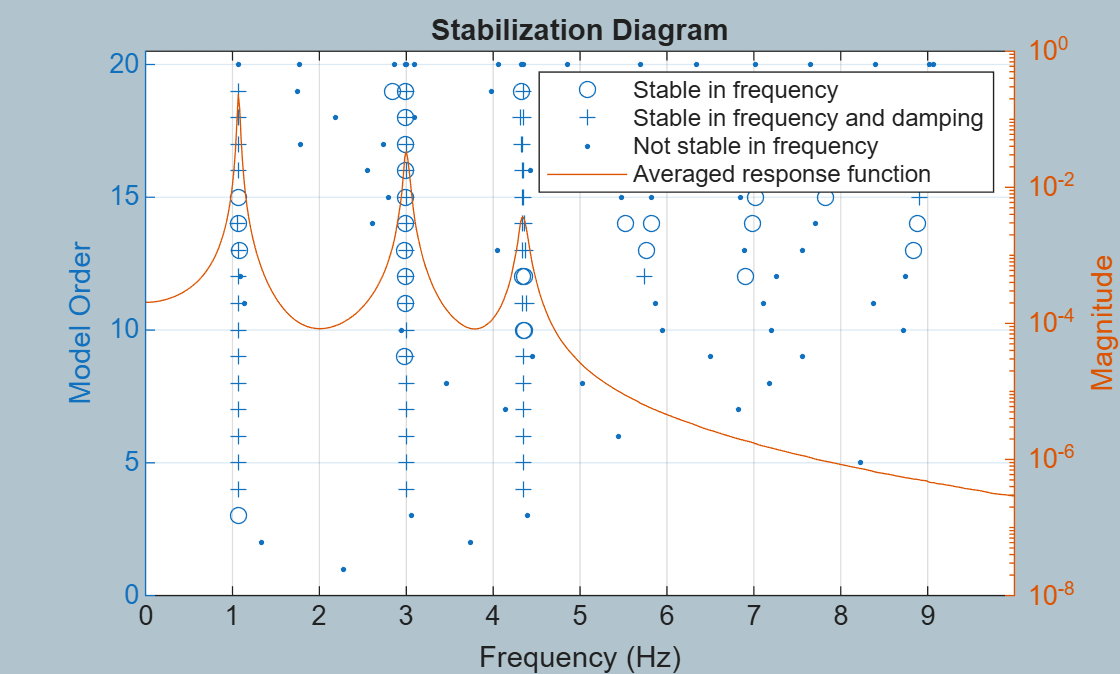

fn_sd =        NaN         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
       NaN       NaN         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.0692       NaN       NaN         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.0706    3.0029    4.3462       NaN         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.0707    3.0034    4.3462       NaN       NaN         0         0         0         0         0         0         0         0         0         0         0         0         0        

MAXMODES = 20;

figure   %  the STABILIZATION plot
    fn_sd = modalsd( meas.frf, meas.f_hz, Fs_hz, ...
                     MaxModes=MAXMODES, ...
                     FreqRange=roi.range_Hz, ...
                     FitMethod=try_it_FitMethod)

Maybe we weren't able to sweep across the desired MAX modes

ACTUAL_MAXMODES = size(fn_sd, 2);     

remove NaNs and ZEROS

FN_HZ_ALL =   rmmissing(fn_sd(:));
tmp_ind   =  FN_HZ_ALL == 0;
FN_HZ_ALL(tmp_ind) = [];

# **STEP_3:**   Look for Clusters from the Stabilization plot

## Explore the distribution of the identified modes

 REMEMBER: many of the modes will NOT be real modes, rather they will be computational ones that we need to ignore. 

### Select modes based on CLUSTERING and a count threshold

 So let's utilize a data **CLUSTERING** algorithm to semi automate where we think the real modes are.  We will need to tune this, e.g.:  

- the **neighborhood radius** may need some "trial/error" tuning.

- the **minimum number of counts** within a cluster may need some "trial/error" tuning.

See:  [`bh_collect_by_clustering()`](matlab:  open bh_collect_by_clustering) which uses the [`dbscan()`](matlab: doc dbscan) function to cluster candidate physical modes

Found 3 candidate modes:
 Mode  1: f = 1.0707 Hz  (count = 24)
 Mode  2: f = 3.0030 Hz  (count = 26)
 Mode  3: f = 4.3458 Hz  (count = 26)


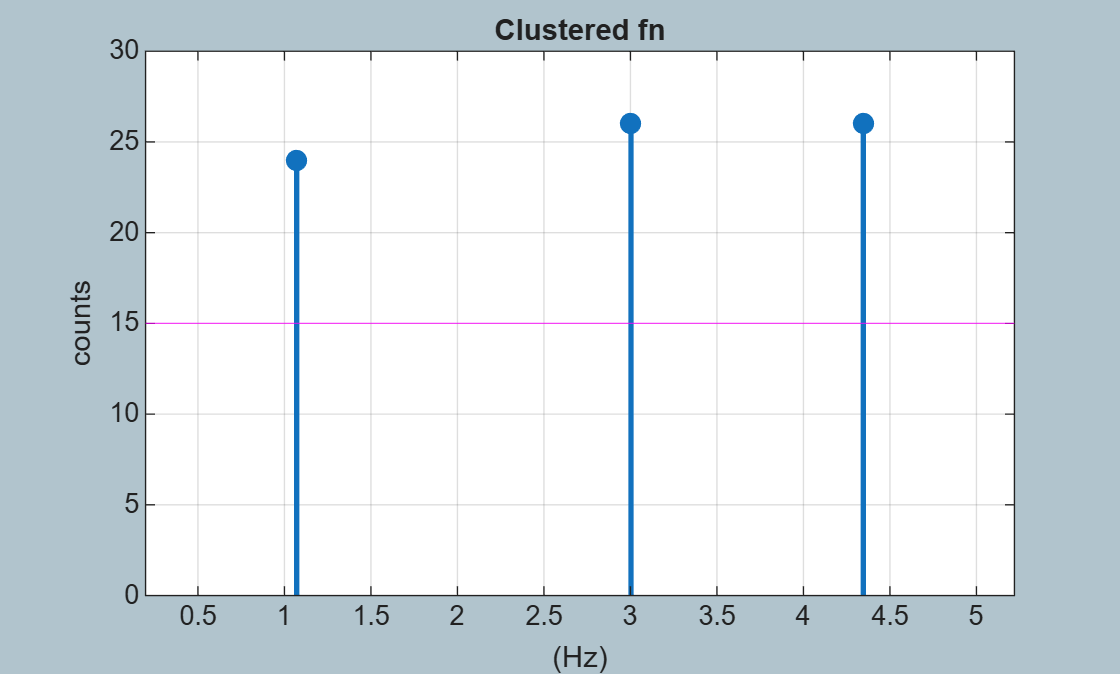

clust_fHz_radius = 0.1;
clust_min_counts = floor(0.75*ACTUAL_MAXMODES);
clust_fHz_range  = roi.range_Hz;

my_fhz_list_FROM_CLUST = bh_collect_by_clustering(FN_HZ_ALL, clust_fHz_radius, clust_min_counts, fHz_range=clust_fHz_range);

So our candidate resonant frequencies $\left\lbrack \mathrm{Hz}\right\rbrack$ are:

my_fhz_list_FROM_CLUST

my_fhz_list_FROM_CLUST =     1.0707
    3.0030
    4.3458


Let's take the first 3

my_fhz_list_FROM_CLUST = my_fhz_list_FROM_CLUST(1:3);

# **STEP_4:**   Extract our Modal Poles

So from the stabilization diagram, how many modes do you think we should try and fit ?

NUM_MODES_TO_FIT = 6    

NUM_MODES_TO_FIT = 6

### Now do a MODAL fit:

- see DOC for [`modalfit()`](matlab:  doc modalfit)

-  **NOTE:**  We'll specify the frequencies extracted from our histogram and pass these into [`modalfit()`](https://au.mathworks.com/help/releases/R2024b/signal/ref/modalfit.html) as 'PhysFreq'.  We'll also specify a HIGHER target number of modes to fit ... to see if there's anything else there. Overspecifying the number of modes gives better (?) results.

[fn,dr,ms] = modalfit( meas.frf, meas.f_hz, Fs_hz, ...
                       NUM_MODES_TO_FIT, ...
                       PhysFreq=my_fhz_list_FROM_CLUST, ...
                       FreqRange=roi.range_Hz, ...
                       FitMethod=try_it_FitMethod);

Remove any Nans:

tmp_ind  = ~isnan(fn) & ~isnan(dr);

fn_clean = fn(tmp_ind);
dr_clean = dr(tmp_ind);
wn_clean = 2*pi*fn_clean;

Tabulate these

array2table([wn_clean, fn_clean(:), dr_clean(:)],'VariableNames',{'wn','fn_hz','zeta'})

ans = 3×3 table
      wn      fn_hz       zeta  
    ______    ______    ________

    6.7276    1.0707     0.01371
    18.871    3.0033    0.010522
    27.308    4.3463    0.012179

	Get insights using Copilot


## Save the results to a MAT file:

 Save the Undamped Natural frequencies to a MAT file

wn_radpersec_original_building = wn_clean;

save bh_SYS_ID_RESULTS             wn_radpersec_original_building
save bh_SYS_ID_RESULTS_CONFIRMED   wn_radpersec_original_building

# **STEP_5:**   Extract our Modal RESIDUES

For some background information on the MODAL model see the following companion document:

- [`APPENDIX_01_Modal_Model_Representation.mlx`](matlab:  open  bh_Modal.APPENDIX_01_Modal_Model_Representation)

Summarize the Identified MODAL properties so far

fprintf("\n FINAL results ----> ")


 FINAL results ----> 

RESULTS_tab = array2table([fn_clean(:), dr_clean(:), (2*pi*fn_clean(:))],...
                            'VariableNames',{'fn_Hz','zeta', 'wn_radpersec'});
RESULTS_tab

RESULTS_tab = 3×3 table
    fn_Hz       zeta      wn_radpersec
    ______    ________    ____________

    1.0707     0.01371       6.7276   
    3.0033    0.010522       18.871   
    4.3463    0.012179       27.308   

	Get insights using Copilot


Recall that we have our measured FRFs in the container

roi

roi = struct with fields:
    range_Hz: [0 10]
        f_Hz: [600×1 double]
         frf: [600×3 double]


% roi.f_Hz     = meas.f_hz(tmp_ind);
% roi.frf      = meas.frf(tmp_ind, :);

## Compute residues:

For each FRF

- 
$$\mathrm{FRF}=\;\left(\sum_{k=1}^N \left.\;\;\frac{R_k }{s-\lambda_k }+\;\frac{\bar{R_k } }{s-\bar{\lambda_k } }\right)\;\;\;+\;\;\;\;\;\frac{f}{s^2 }\;\;\;+\;\;\;\;\;\;e\right.$$


Compute the residues for every each mode in each FRF

- `size(my_R_mat) == NUM_MODES x NUM_CHANNELS`

We'll use a custom function to do this:    [`bh_Modal.bh_calc_resids_LIVE()`](matlab:  edit bh_Modal.bh_calc_resids_LIVE) 

-  I'd also recommend doing `PRIMER_03` for a deeper discussion on extracting the RESIDUES

my_R_mat = NaN( length(fn_clean),  size(roi.frf, 2) );

for kk=1:size(my_R_mat,2)
 
    [my_R, my_e, my_f]  = bh_Modal.bh_calc_resids_LIVE( fn_clean, ...
                                                        dr_clean, ...
                                                        roi.f_Hz, ...
                                                        roi.frf(:,kk)    );
    my_R_mat(:,kk) = my_R;
end

Visually confirm Residues have phases close to 90 degrees OR -90 degrees

-  **NOTE:** each ROW of the following matrix contains the **residue PHASE** for a given **"mode shape"** vector

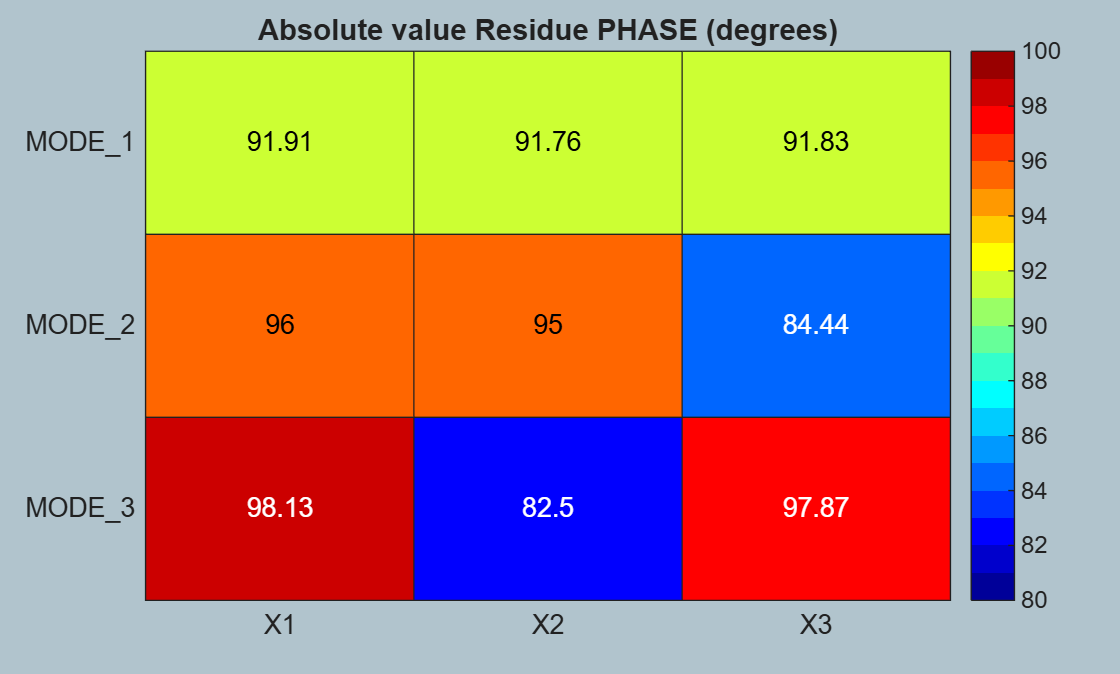

tmp_res_phas_degs = abs( rad2deg(angle(my_R_mat)) );

figure;
    heatmap( tmp_res_phas_degs, "Colormap", jet(20), ...
             YDisplayLabels="MODE_"+(1:height(my_R_mat)), ...
             XDisplayLabels=out_dof_labels, ...
             Interpreter="none");
        title("Absolute value Residue PHASE (degrees)")
         clim([80 100])

## Extract Mode shapes and plot them

Recall the format of our RESIDUE matrix

- `size(my_R_mat) == NUM_MODES x NUM_CHANNELS`

Assume Proportional damping and convert the Residues into normal mode data

 **NOTE:** each ***ROW*** of the following matrix is a **"mode shape"** vector

- For the rationale on this, see [`APPENDIX_01_Modal_Model_Representation.mlx`](matlab:  open  bh_Modal.APPENDIX_01_Modal_Model_Representation)

md_shapes = imag(my_R_mat);

Plot the mode shapes

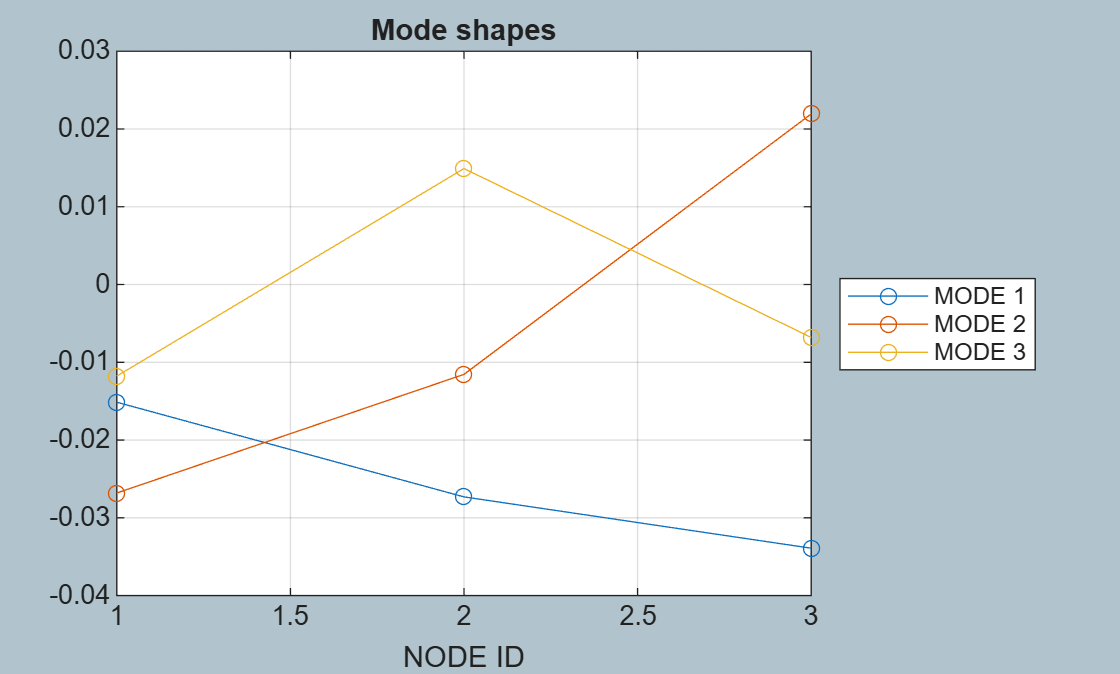

figure;
  for kk=1:size(md_shapes,1)
    % extract mode KK
    plot(md_shapes(kk,:), "-o", "DisplayName","MODE "+kk);
    hold on
  end
  grid("on")
  xlabel("NODE ID")
  legend('Location','eastoutside')
  title("Mode shapes")

 **Pause and Ponder.**  So it appears that:

- $\omega_1$  causes $z_3$ to have the largest displacement

- $\omega_2$  causes $z_1$ to have the largest displacement

- $\omega_3$  causes $z_2$ to have the largest displacement

# Compare Measure FRF against Fitted FRF

## So what does the curve fit look like ?

We've completed the curve fit.  So let's combine our identified terms into a final model:

- 
$$\mathrm{FRF}=\;\left(\sum_{k=1}^N \left.\;\;\frac{R_k }{s-\lambda_k }+\;\frac{\bar{R_k } }{s-\bar{\lambda_k } }\right)\;\;\;+\;\;\;\;\;\frac{f}{s^2 }\;\;\;+\;\;\;\;\;\;e\right.$$


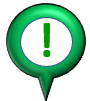We'll use a custom **Value Class** defined in the file  [`CLS_sdyn_frf.m`](matlab:  edit  bh_Modal.CLS_sdyn_frf) to represent the FRF

- `CLS_sdyn_frf(the_damping_zeta, ``the_wn_rads``, the_R, the_E, the_F)`


---------------------------------------------------------------------------
 ID_label = sdt_foo

 mode#      Wn[Hz]       DAMP[-]       Real(R)          Imag(R)        Phase(R)[degs]      
  1          1.071      0.01371      -0.000505295       -0.0151387     -91.91  
  2          3.003      0.01052       -0.00281663       -0.0268123     -96.00  
  3          4.346      0.01218       -0.00168277       -0.0117787     -98.13  

 E = 1.18552e-05 + i*-2.98855e-05
 F = -7.32268e-07 + i*-3.57803e-07

Current plot held


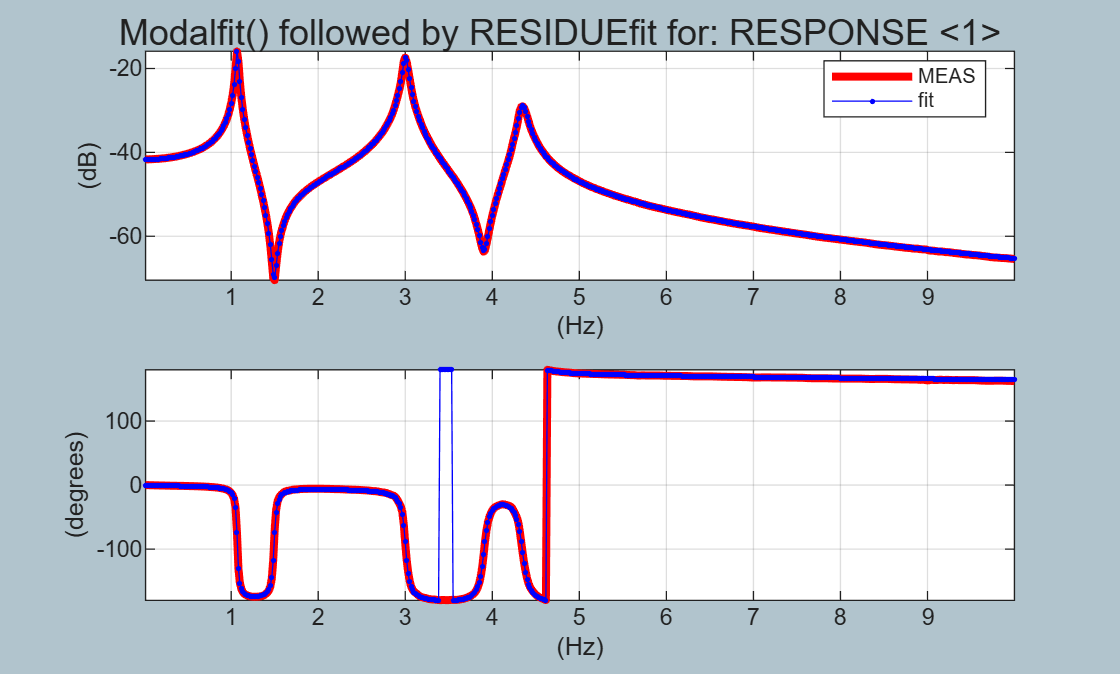

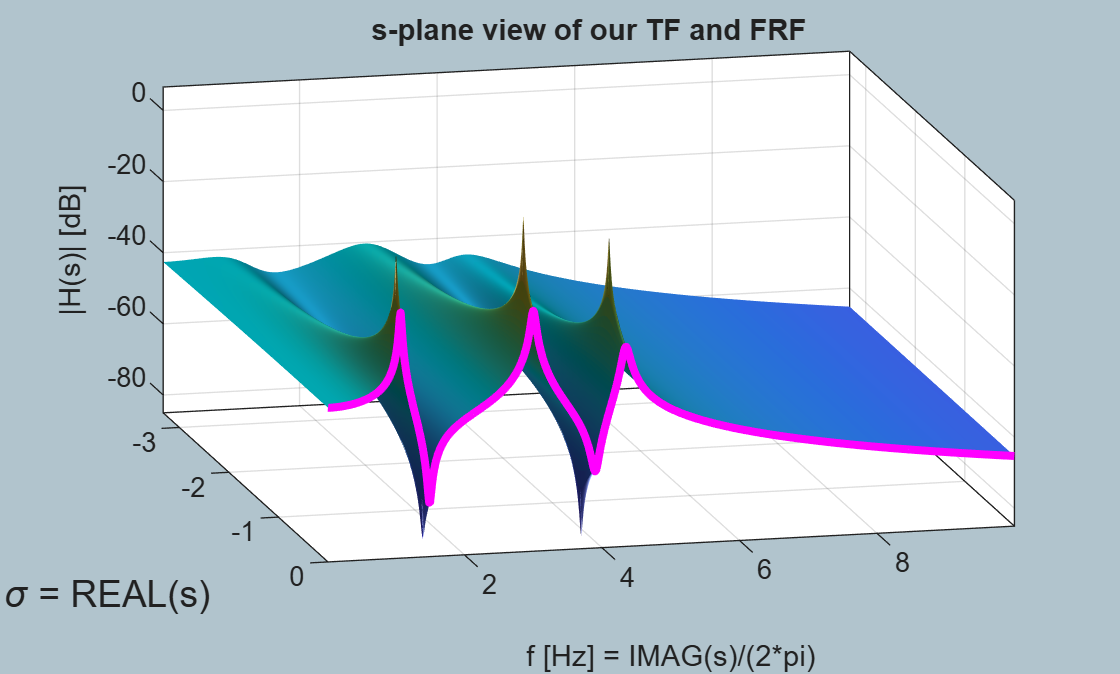


---------------------------------------------------------------------------
 ID_label = sdt_foo

 mode#      Wn[Hz]       DAMP[-]       Real(R)          Imag(R)        Phase(R)[degs]      
  1          1.071      0.01371      -0.000838712       -0.0273115     -91.76  
  2          3.003      0.01052       -0.00101066       -0.0115517     -95.00  
  3          4.346      0.01218         0.0019625        0.0149135      82.50  

 E = -4.75693e-07 + i*5.71699e-06
 F = 8.7348e-08 + i*1.21187e-07

Current plot held


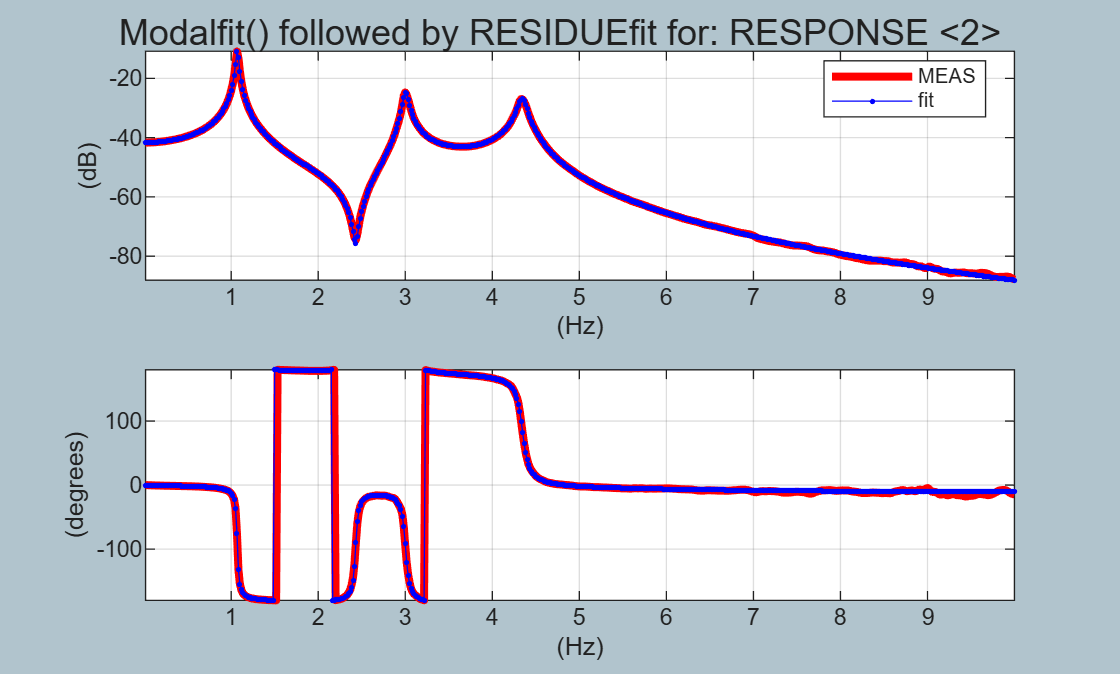

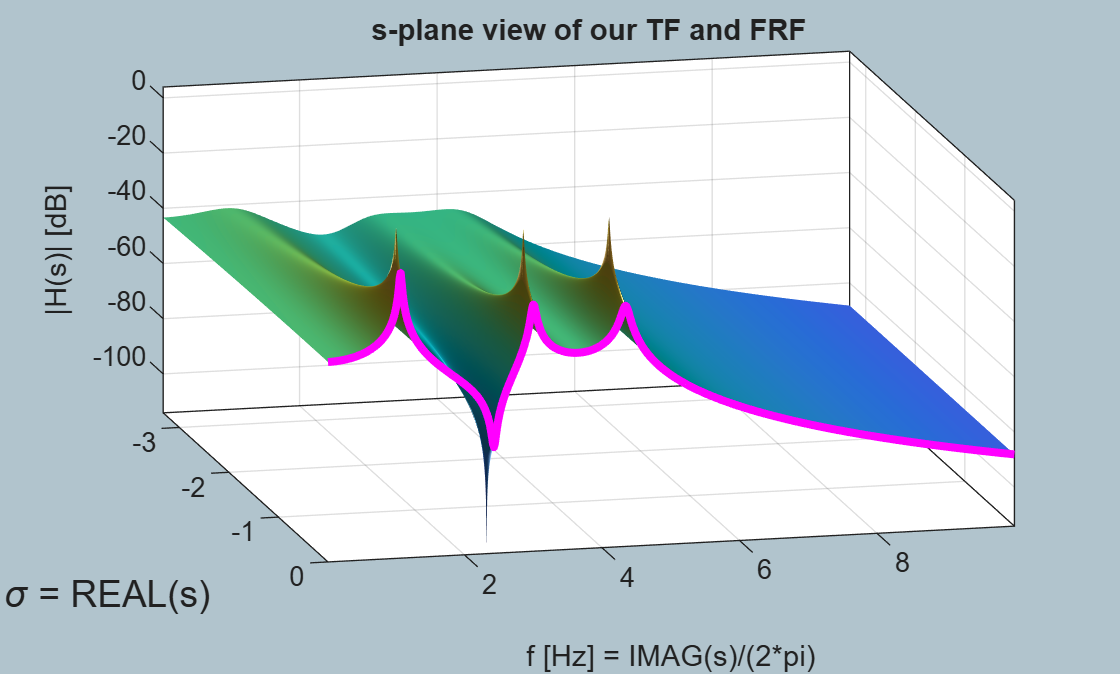


---------------------------------------------------------------------------
 ID_label = sdt_foo

 mode#      Wn[Hz]       DAMP[-]       Real(R)          Imag(R)        Phase(R)[degs]      
  1          1.071      0.01371       -0.00108075       -0.0339105     -91.83  
  2          3.003      0.01052        0.00213531        0.0219422      84.44  
  3          4.346      0.01218      -0.000940796      -0.00680858     -97.87  

 E = 2.07892e-06 + i*1.29133e-06
 F = 2.781e-07 + i*7.70297e-08

Current plot held


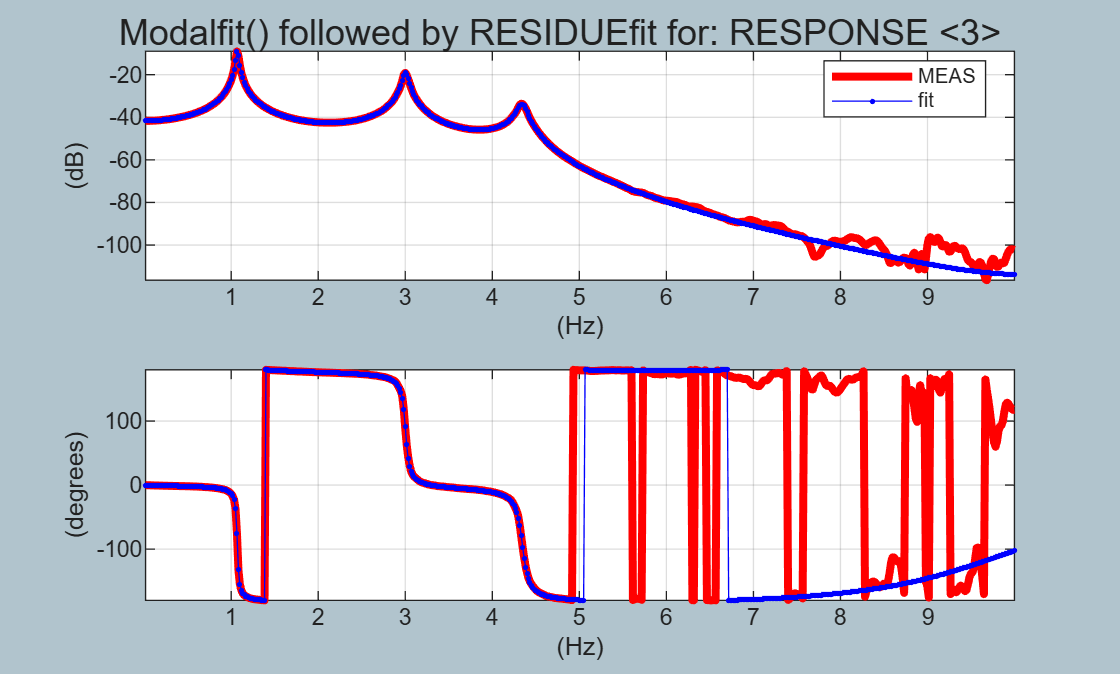

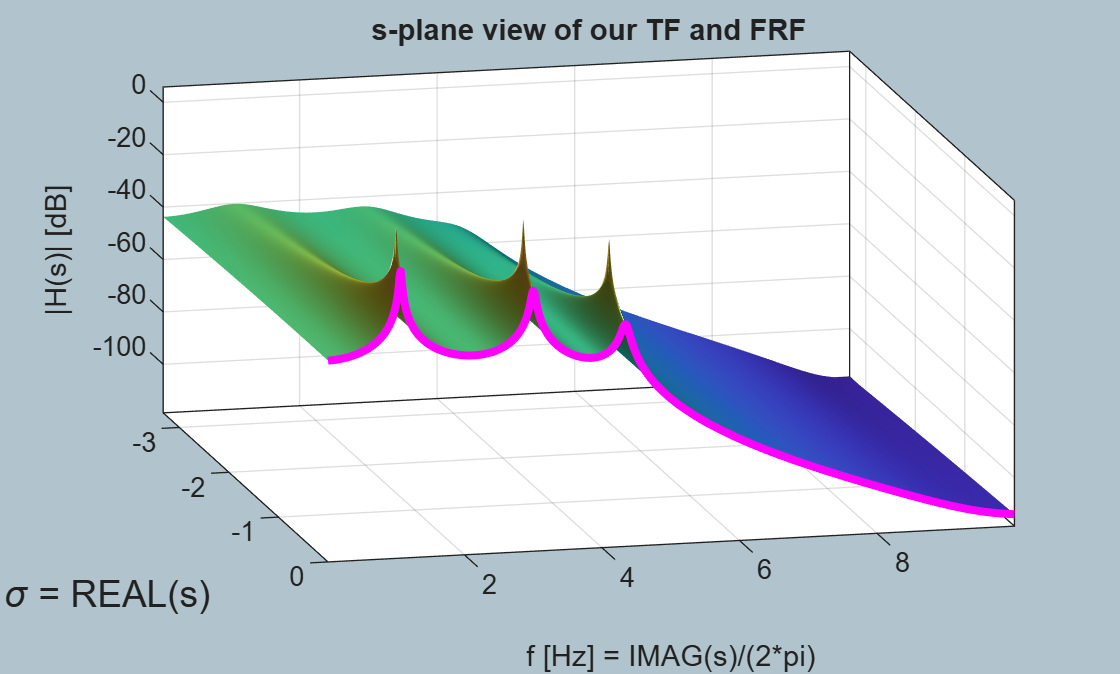

for kk=1:size(roi.frf, 2)
 
  [my_R, my_e, my_f]  = bh_Modal.bh_calc_resids_LIVE( fn_clean, ...
                                                        dr_clean, ...
                                                        roi.f_Hz, ...
                                                        roi.frf(:,kk)    );

  my_sdyn_OBJ = bh_Modal.CLS_sdyn_frf( RESULTS_tab.zeta,         ...
                                       RESULTS_tab.wn_radpersec, ...
                                       my_R, my_e, my_f);

  my_sdyn_OBJ.s_w_fhz_col = roi.f_Hz;
  
  %Echo a summary of our model:
  my_sdyn_OBJ.print()

  % Plotting:  Part 1 - Plot the model against the Measurement data
  figure;
      hax(1) = subplot(2,1,1); 
           plot(roi.f_Hz, 20*log10(abs(roi.frf(:,kk))), "-r", "LineWidth",3,"DisplayName","MEAS")
               grid on; axis tight
               xlabel("(Hz)");   ylabel("(dB)");
               
      hax(2) = subplot(2,1,2); 
           plot(roi.f_Hz, rad2deg(angle(roi.frf(:,kk))), "-r", "LineWidth",3)
               grid on; axis tight
               xlabel("(Hz)");  ylabel("(degrees)")
    
  hold(hax(1),"on")
        axes(hax(1))
        plot(my_sdyn_OBJ.s_w_fhz_col, my_sdyn_OBJ.db, "-b.","DisplayName","fit");
    
  hold(hax(2))
        axes(hax(2))
        plot(my_sdyn_OBJ.s_w_fhz_col, my_sdyn_OBJ.phase("DEGS"), "-b.");
    
  legend(hax(1), "Location", "best")
    
  linkaxes(hax, "x")
    sgtitle("Modalfit() followed by RESIDUEfit for: RESPONSE <"+kk+">")


  % Plotting:   Part 2 - Plot the model FRF in 3D
  my_sdyn_OBJ.plot_3d_db()
  drawnow
end

And we are done